# **PSYC 574C Term Project - Modelling RL in Blackjack**

clear
close all
clc
rng('shuffle')

**We'll start with a basic demonstration of the Blackjack paradigm, and then dive into building a reinforcement learning model to learn the task.**

### **Blackjack Rules and Strategy**

In Blackjack, players are dealt two cards and play opposite a "dealer" opponent. In each ‘hand’, the player views their two cards and determines whether they want to ‘Hit’ for additional cards or ‘Stay’ with their current cards to outscore the dealer. However, if their score exceeds 21 they lose - this is called a 'Bust'. 

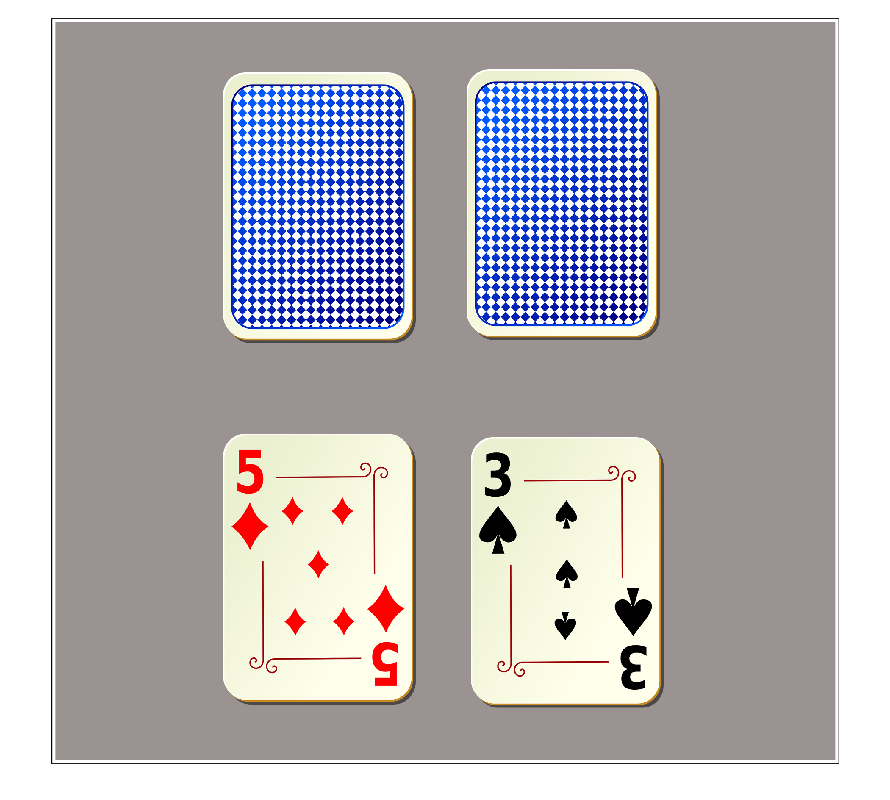

sampleHand=imread("SampleBlackjack.png");
imshow(sampleHand)

Cards are worth as many points as their numbered value, face cards are worth 10 points, and aces were worth 1 or 10 points dependent on which was better for the participant’s score. Consider the example to the right - the player is dealt a 5 and 3, which means their score is 8. They should probably 'Hit' for another card - they cannot 'Bust' because there isn't a card that would put them over 21, and the dealer is likely to have a larger score than 8.

Based on these rules, an "optimal", but not guaranteed, strategy emerges. By considering the score of the player's hand and how many cards in a given deck would cause the current hand to 'Bust', the player can weigh how valuable it is to 'Hit' or 'Stay'. Importantly, Blackjack rules vary from casino-to-casino (ex. how many decks are shuffled into play, the dealer's behaviour), but the general pattern of optimal performance follows a sigmoidal pattern with increasing score.

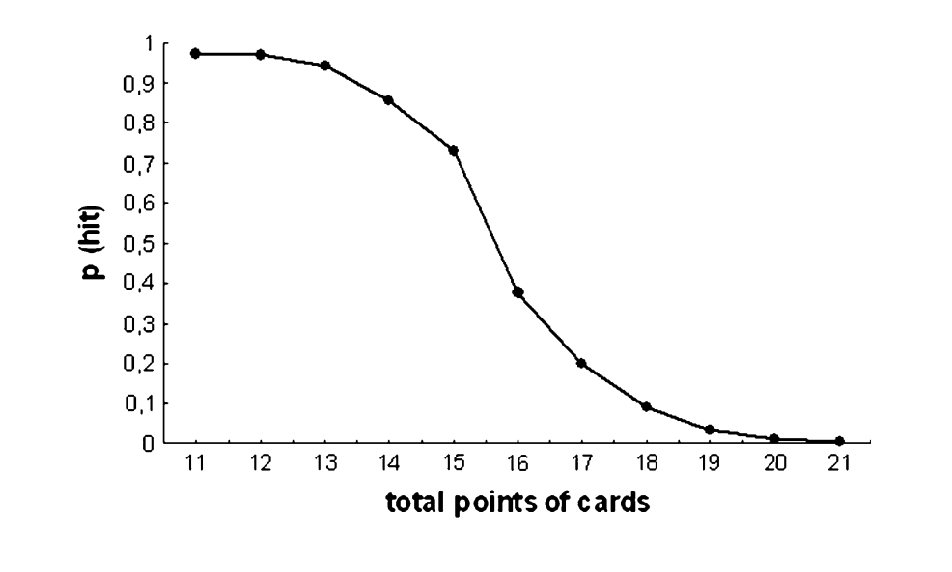

strategy = imread("BlackjackStrategy.png");
imshow(strategy)

The figure to the right, replicated from Hewig et al. (2007), demonstrates this well. Players should 'Hit' on every trial with a score of 11 or less, since there is no possibility of a 'Bust'. Then, the probability of a 'Hit' should decrease sharply around 15 - this is the inflection point of the sigmoid curve, and will be important later. Scores less than 15 are less likely to 'Bust' because they need to be dealt a high card, so players should 'Hit'. Scores larger than 15 should indicate a 'Stay' since players will likely outscore the dealer and have a high risk of going over 21 if they 'Hit'. 

However, while this strategy is optimal, it is not perfect. Players can lose with 19, or even 'Bust' and lose on a 12. As such, to "learn" Blackjack, players really have to learn this response curve - it is their best route to winning more hands (and of course, more money). 

## **Can a simple Reinforcement Learning model learn Blackjack?**

The prominent theory on reward processing indicates humans rely on a midbrain reinforcement learning (RL) system that guides behaviour. Specifically, this theory suggests that we compute prediction errors – differences between expected and actual outcomes – and use them to guide action selection. 

Interestingly, this RL system is still highly active in scenarios where learning is unnecessary, or impossible.  Consider Blackjack - are humans using an RL system to guide behaviour in scenarios where learning does not guarantee success? Here, I will attempt to determine if a simple RL model can learn optimal strategy in Blackjack.

The theory behind the model is discussed in depth in the companion Observable notebook and Word document, but here I will demonstrate practical considerations for its' construction. To test the model, I will compare its score-action values, which are analogous to the probability the model will 'Hit' or 'Stay' on a given hand, to a sigmoidal curve representing optimal Blackjack strategy.  

### **Building the Model**

Let's start by defining the initial parameters of the model. We'll start with the intial weights for each action for each given score. Because we can decide to hit or stay on every trial, and we can be dealt a maximum of 20 points, we'll start with a 20 x 2 matrix of repeated values of 0.5. We'll also start with a temperature of 1.5 and learning rate of 0.2, to ensure the model explores relatively frequently but doesn't get hung up on highly unexpected outcomes. 

initialWeights = repmat(0.5, [20,2]); % Store the weights in a scores x actions matrix
temperature = 1.5; % Temperature is the exploratory part of the model
learningRate = 0.20; % Lets start with a lower learning rate

Next, we'll determine how the model will complete the task. For this demo, I've set the number of trials to be quite low, as the model can be quite slow at high counts. We'll take a look at runs with high trial counts later. 

numberOfTrials = 500;
behaviouralData = NaN(numberOfTrials,9); %Empty a matrix to store the model's behaviour
extensiveWeights = NaN(numberOfTrials,20,2); %Store all the weights for each trial, score, and action

Now, we can finally jump into the task. The next code block contains the model's attempt to learn the task. 

% We'll randomly select a trial from the second half of the run.
% (we need this to look at a sample hand).
trialSelector = randi(numberOfTrials/2)+(numberOfTrials/2);

% We'll also load in some card names and point values.
cardValues = readtable("cardValues.xlsx"); %Load in a table with playing card names and point values
cardValues.Properties.VariableNames= {'Card #','Score','Name','Suit'};

weights = initialWeights; %Make a new variable to store weights
for trialCounter = 1:numberOfTrials

    deck = cardValues; %Load in the card values for a deck of 52 cards


First, we have to "deal" cards to the model. 


    % Player first, just like Vegas!
    firstCard = randi(height(deck),[1,1]); %Randomly select one card to deal to the player
    firstCardValue = table2array(deck(firstCard,2)); %Record the point value of that card
    deck(firstCard,:) = []; %Remove that card from the deck

    %Repeat the deal for the player's second card
    secondCard = randi(height(deck),[1,1]);
    secondCardValue = table2array(deck(secondCard,2));
    deck(secondCard,:) = [];

    %Determine the combined score of the 2 cards
    startScore  = firstCardValue+secondCardValue;

    %Now the dealer
    dFirstCard = randi(height(deck),[1,1]);
    dFirstCardValue = table2array(deck(dFirstCard,2));
    deck(dFirstCard,:) = [];

    dSecondCard = randi(height(deck),[1,1]);
    dSecondCardValue = table2array(deck(dSecondCard,2));
    deck(dSecondCard,:) = [];

    dealerScore = dFirstCardValue+dSecondCardValue;



Now, we determine what choice the model will make. This is where *Equation 1* comes in - a softmax decision rule considering the score of the hand, and the values of each action based on that score. 

$P(s,a_i)=\frac{e^{\frac{V(s,a_i)_t}{\tau}}}{\sum^2_{j=1} e^{\frac{V(s,a_j)_t}{\tau}}}$    (1)

    %% Choice
    if trialCounter == 1
        choice = randi(2,[1,1]); %On the first trial, the choice to hit or stay is random
    else
        %Determine the denominator of the softmax function
        softMaxDenom = sum(exp(weights(startScore,:)/temperature)); %This is the same for hits and stays

        %Determine the numerator for a hit choice for this value
        softMaxNumeratorHit = exp(weights(startScore,1)/temperature);

        softMaxProbHit = softMaxNumeratorHit/softMaxDenom; %Determine softmax prob of hitting

        %Repeat for stays
        softMaxNumeratorStay = exp(weights(startScore,2)/temperature);
        softMaxProbStay = softMaxNumeratorStay/softMaxDenom;


        %If the softmax prob is larger for hitting,
        if softMaxProbHit>softMaxProbStay
            choice = 1; %Hit for another card
        elseif softMaxProbStay>softMaxProbHit %If its larger for staying,
            choice = 2; %Stay with the current card
        else %If the probabilties are equal
            choice = randi(2,[1,1]);
        end

    end

    if choice == 1 %If the player hits for another card,
        nextCard = randi(height(deck),[1,1]);  % Select a new card,
        nextCardValue = table2array(deck(nextCard,2)); %Determine it's value
        deck(nextCard,:) = []; %Remove it from the deck
        currentScore = startScore+nextCardValue; %Add the score to the hand
    else
        currentScore = startScore; %We reallocate startScore to currentScore even without a hit for cleaner syntax
    end



 Now we'll simulate the dealer's choice, just to fairly determine the outcome. This does not effect the model's choice! 


    while dealerScore <= 16 %Dealers must hit on all 16s or less
        dNextCard = randi(height(deck),[1,1]);
        dNextCardValue = table2array(deck(dNextCard,2));
        deck(dNextCard,:) = [];

        dealerScore = dealerScore+dNextCardValue;
    end

Next, we determine what the outcome is. 

    difference = 21-currentScore; %Determine how far from 21 the player is

    if currentScore>21 %If the player "busted",
        outcome = -1; %Loss!
    else %If the player didn't bust,

        %The player has to outscore the dealer, ties go to the dealer.

        if currentScore <dealerScore && dealerScore <= 21 %If the player scored less than the dealer, and dealer didn't bust,
            outcome = -1; %Loss1
        else
            outcome = 1; %If the player scored 21 or beat the dealer (the dealer scored lower or busted)
        end

    end



Finally, based on the outcome and the values of the choice we selected, we compute a prediction error (*Equation 2 *and update those values accordingly (*Equation 3)*. 

$\delta = r  - V(s,a_i)_t$     (2)

$V(s,a_i)_{t+1} = V(s,a_i)_t + (\delta\alpha \cdot N(s,1))$    (3)

    %% Update the RL Model
    predictionError = outcome - weights(startScore,choice);

    updateFunction = learningRate*predictionError;

    previousWeights = weights(startScore,:); %Store the value before updating.
    weights(:,choice) = weights(:,choice)+(updateFunction*normpdf(1:1:20,startScore,1))';

    % In traditional RL fashion we will cap the weights at the "True" value
    % maxes. In other words, no value should exceed absolute certainty of
    % choice - the weight for hitting or staying cannot exceed 1 and -1,
    % respectively.
    if weights(:,choice) > 1
        weights(:,choice) = 1;
    end

    if weights(:,choice) < -1
        weights(:,choice) = -1;
    end

    if trialCounter == trialSelector-1
        oldWeights = weights;
    elseif trialCounter == trialSelector
        newWeights = weights;
    end

    extensiveWeights(trialCounter,:,:) = weights;
    behaviouralData(trialCounter,:) = [startScore,currentScore,dealerScore,choice,previousWeights(1,1),previousWeights(1,2),weights(startScore,choice),outcome,predictionError];

end


That is a lot to handle, so let's take a look at a sample trial. 



startingScore = behaviouralData(trialSelector,1); %Get the score of the hand
hitValue = behaviouralData(trialSelector,5); %Get the 'Hit' value before the outcome
stayValue = behaviouralData(trialSelector,6); %Get the 'Stay' value before the outcome

disp(['The model was dealt cards valued at ' num2str(startingScore) '.'])

The model was dealt cards valued at 20.


disp(['Before this trial, the model had a value of ' num2str(round(hitValue,2)) ' for hitting,'])

Before this trial, the model had a value of 0.5 for hitting,


disp(['and a value of ' num2str(round(stayValue,2)) ' for staying on a ' num2str(startingScore) '.'])

and a value of 0.84 for staying on a 20.



if behaviouralData(trialSelector,4) == 1
    thisText = 'Hit';
    thisChoice = 1;
else
    thisText = 'Stay';
    thisChoice = 2;
end

disp(['Based on this, the model decided to ' thisText '.'])

Based on this, the model decided to Stay.


if behaviouralData(trialSelector,8) == 1
    disp(['The model won this hand, leading to a positive prediction error of '...
        num2str(behaviouralData(trialSelector,9)) '.']);
else
    disp(['The model lost this hand, leading to a negative prediction error of '...
        num2str(behaviouralData(trialSelector,9)) '.']);
end

The model won this hand, leading to a positive prediction error of 0.1642.


Now, the model updates it's values based on the update function (equation 3 in the Observable notebook writeup). Here's an example of what that looks like for all of the score-action values for the chosen action. 

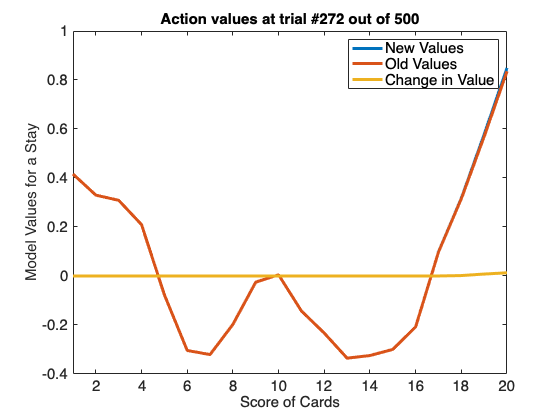

figure;
plot(1:20,newWeights(:,thisChoice),'LineWidth',3)
hold on;
plot(1:20,oldWeights(:,thisChoice),'LineWidth',3)
hold on;
plot(1:20,newWeights(:,thisChoice) - oldWeights(:,thisChoice),'LineWidth',3)
xlim([1,20])
xlabel('Score of Cards')
ylabel(['Model Values for a ' thisText])
legend({'New Values','Old Values','Change in Value'})
title(['Action values at trial #' num2str(trialSelector) ' out of ' num2str(numberOfTrials)])
hold off
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 15)

**There are two important characteristics of the change in score-action values: **

First, you should notice that the change in value is flat for most of the scores, but peaks at the score of the current hand, and stretches into the two neighbouring values. Although, if the displayed hand has a score of 2 or 20 this will be less apparent - you can just re-run the script to get a better sample hand. 

Second, you probably noticed that the change in value is pretty small. Recall we have a pretty small learning rate - our score-action values do not drastically change. Because Blackjack is still highly chance-based, we do not want to change our values without plenty of evidence. As such, the smaller learning rate ensures that unlikely chance-based outcomes, such as losing on a 19, don't significantly drive behaviour.

### Did the model actually "learn" the task? 

Okay, let's see if the model successfully learned the task. The short answer is no - it did not! Let's see why.

We will focus on the model's behaviour for scores of 10-20 because scores of less than 10 are relatively unlikely in Blackjack and the model cannot explore them enough to learn accurate score-action values. We'll also focus on the difference in values for hitting and staying at the end of the model's run - roughly representing the likelihood the model will hit on that score. 

hitOverStay = weights(10:20,1)-weights(10:20,2); % Hit - stay
possibleScores = linspace(10,20,11)'; %Focus on 10-20

First, we have to make a sigmoidal curve to fit our data to (*Equation 4*). The curve should have an inflection point around a score of 15 and encapsulate values from -1 to 1. We set this ideal curve to these limits to reflect the bounds we set on the score-action values earlier. 


$$f(x) = (U-L) \cdot \left( \frac{1}{1+e^{-b(x-c)}} \right)-L$$


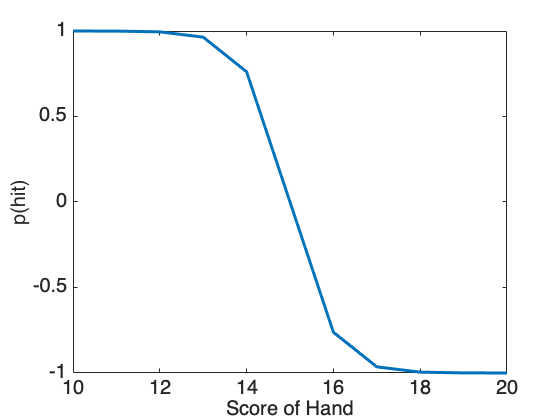

%Create a sigmoidal curve based on Equation 4, with two set parameters.
b = -2; c = 15; U = 1;L=-1;
sigmoid = @(x) (U-L)*(1./(1+exp(-b*(x-c))))+L;

x = possibleScores;
y = sigmoid(x);
plot(x,y,'LineWidth',3);
xlabel( 'Score of Hand', 'Interpreter', 'none' );
ylabel( 'p(hit)', 'Interpreter', 'none' );
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 20)

This should look familiar as our optimal Blackjack strategy from earlier. Now, we can try fitting the model to this curve, using the MATLAB curve-fitting tool.

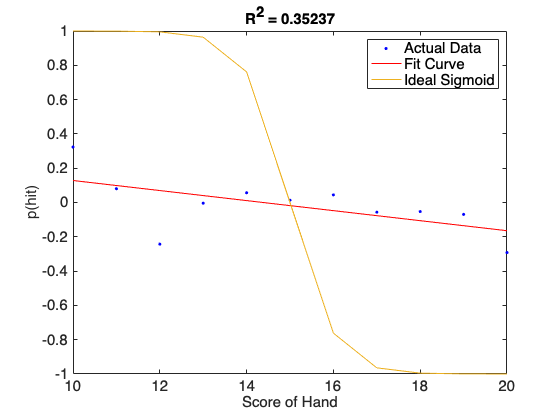

%We'll set up the fit by first selecting our fit method,
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';

%plugging our sigmoid curve into a custom fittype variable,
ft = fittype( '(U-L)*(1./(1+exp(-b*(x-c))))+L', 'independent', 'x', 'dependent', 'y','coefficients',{'b','c','L','U'});

% and then determing the search spaces for our parameters b,c,U,andL.

opts.Lower = [-20 1 -5 0];
opts.Upper = [10 20 0 10];
%-1 is a good sharpness (again, piloting) so we start with b = -1
%15 is where the curve sharpens, so we start with a c = 15
opts.StartPoint = [-8 15 min(hitOverStay) max(hitOverStay)];

%Finally, we'll check our fits!
[fitresult, gof] = fit( possibleScores, hitOverStay, ft, opts );

plot(fitresult,possibleScores,hitOverStay);
hold on
plot(possibleScores,y)
xlabel( 'Score of Hand', 'Interpreter', 'none' );
ylabel( 'p(hit)', 'Interpreter', 'none' );
legend({'Actual Data', 'Fit Curve','Ideal Sigmoid'});
title(['R^2 = ' num2str(gof.rsquare)])
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 15)

Now, the results of this can vary wildly - run the script a few times and you'll see plenty of differences between the fit curve and the shape of our sigmoid, as well as the upper and lower bounds of that fit curve. You'll also see that the $R^2$ will drastically change, and may be deceivingly high for a curve that does not look sigmoidal. 

The model is unlikely to consistently learn the task in 500 trials with these parameters. The model cannot always experience enough outcomes for each score and each action to build out optimal score-action values. Since Blackjack is highly chance-based, the model is seeing too many outcomes that violate optimal strategy compared to outcomes that agree with optimal strategy. 

**In other words, the task is too complex to learn quickly. **

So, how much experience does the model need? I have trained the model on 100, 500, 5,000, and 10,000 trials of Blackjack, 10 times each, and saved the data so you don't have to (this can take a long time). We can compare the model fits from these runs to determine when the model is consistently learning optimal strategy. 

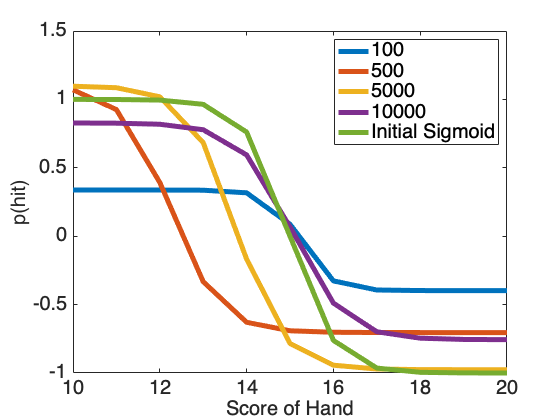

iterations = [100,500,5000,10000]; 

figure;
for trialCount = 1:4 %For each trial count iteration
    files = dir(['Sample Data/*_' num2str(iterations(trialCount)) '.mat']); %isolate relevant data

    for i = 1:length(files) %For each of the 10 runs, 
        load(fullfile(files(i).folder,files(i).name))
        %isolate the parameters
        bF(trialCount,i) = outputData.fit.b; 
        cF(trialCount,i) = outputData.fit.c;
        uF(trialCount,i) = outputData.fit.U;
        lF(trialCount,i) = outputData.fit.L;

        wins = outputData.behaviour(:,6) == 1;
        accuracy(trialCount,i) = sum(wins)/iterations(trialCount);

        %and gof
        r2(trialCount,i) = outputData.gof.rsquare;
    end

    %Plug in the mean parameters from all the fits
    mB = squeeze(mean(bF(trialCount,:),2));
    mC = squeeze(mean(cF(trialCount,:),2));
    mU = squeeze(mean(uF(trialCount,:),2));
    mL = squeeze(mean(lF(trialCount,:),2));
    sigmoid = @(x) (mU-mL)*(1./(1+exp(-mB*(x-mC))))+mL;

    x = possibleScores;
    plotData(trialCount,:) = sigmoid(x);
    plot(x,plotData(trialCount,:),'LineWidth',5)
    hold on
end

plot(x,y,'LineWidth',5)
hold on

xlabel( 'Score of Hand', 'Interpreter', 'none' );
ylabel( 'p(hit)', 'Interpreter', 'none' );
legend({'100','500','5000','10000','Initial Sigmoid'})
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 20)
hold off

Visually, it's looking like the model gets closer to the idealized sigmoid function with increasing trial counts. 

With 100 trials we actually do reasonably well, but the p(hit) is generally quite small. In practice, the model "isn't sure" about its decision making, indicating this fit could actually be chance-based and not extend well to further testing. Recall when re-running this model (set to 500 trials) changed the shape of the value functions drastically, so 100 trials is still likely inconsistent. 

With both 500 and 5000 trials, the models hit their inflection point much sooner - opting to play more conservatively and 'Stay' on lower scores more often.

With 10000 trials, that inflection point is very similiar to the ideal sigmoid shape, but with slightly tighter bounds. 

We'll try a crude measure to see just how close each iteration was to getting the optimal strategy right. We can see how far each model run was from *c = 15*, i.e. recognizing that a score of 15 is when the odds of successfully hitting to win reduce drastically. The closer the model fit's *c* is to 15, the closer to the real strategy is. 

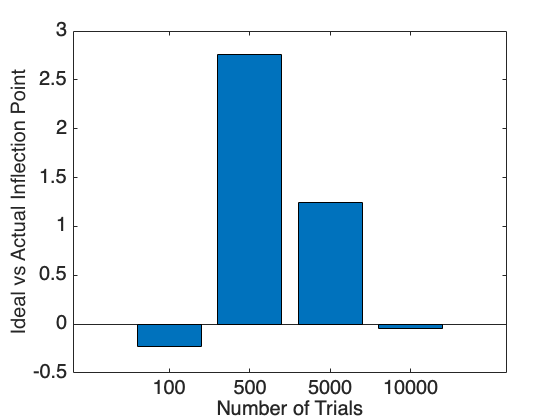

diffCValues = 15-cF;
meanDiffC = mean(diffCValues,2);
figure;
bar(meanDiffC','grouped');
xticks(1:4)
ylabel('Ideal vs Actual Inflection Point')
xlabel('Number of Trials')
xticklabels({'100','500','5000','10000'});
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 20)

As before, we see that the runs with 100 trials of Blackjack converge pretty close to the ideal inflection point. But also not that the runs with 500 trials does not! Again, this reflects the inconsistency in performance for each iteration with lower trial counts. 

**Tenatively, we can say the model learned with 10000 trials of Blackjack!** We can quantify this (albeit somewhat crudely) with $R^2$. 

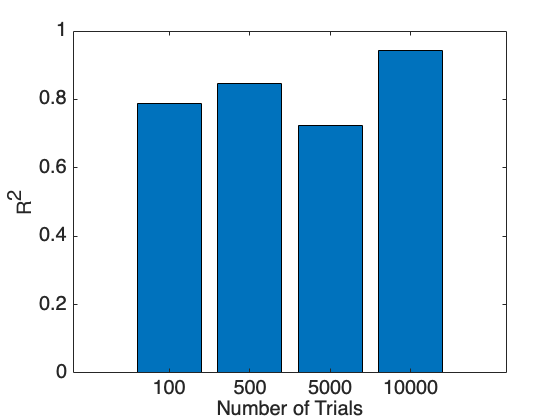

figure;
meanGOF = squeeze(mean(r2,2));
bar(meanGOF','grouped');
xticks(1:4)
ylabel('R^2')
xlabel('Number of Trials')
xticklabels({'100','500','5000','10000'});
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 20)

If anything this plot shows how deceptive model fitting with $R^2$ can be. Take the iteration with 500 trials of Blackjack training. Its possible that, because$R^2$ isn't considering the functional form of the models we're fitting, its reflecting variance accounted for from the *b* parameter rather than the *b *and *c *parameters. As such, we are fooled into thinking our conservative model that doesn't hit above 13 is good at Blackjack! 

This is the conclusion of the demonstration, more information is included in the Observable notebook!